get paths, clear workspace

filePath = matlab.desktop.editor.getActiveFilename;
cd(filePath(1:strfind(filePath,'livescripts/cell_mig')-1))
addpath(genpath(filePath(1:strfind(filePath,'livescripts/cell_mig')-1)));
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')

load for mean-field discovery

dr = '/home/danielmessenger/Dropbox/Boulder/research/data/wound_healing/';
% load([dr,'20240321/trackedData.mat'])
load([dr,'20240530/r02c09f07.mat'])
% load([dr,'20240531/r02c09f07.mat'])

N = tracks.NumTracks;
M = tracks.MaxFrame;
X = zeros(N,2,M)+NaN;
clf
for n=1:N
    X(n,:,tracks.Tracks(n).Frames) = cell2mat(tracks.Tracks(n).Data.Centroid')';
    % X(n,1,:) = fillmissing(X(n,1,:),'linear','EndValues','none');
    % X(n,2,:) = fillmissing(X(n,2,:),'linear','EndValues','none');
end
t = 0:8/60:(M-1)*8/60;
Xscell = {X};

Compute approximate particle distribution $U$ from particles *Xscell* 

exps = 1; %choose experiments from Xscell to use in regression (if Xscell contains multiple exps)
NN = N; %choose number of particles to use from each experiment
numx = 24 + 1; %choose histogram grid resolution
numsdv = inf;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0.05 1 1]];
scoord = 0;
Xsnz = [0 1]; %set extrinsic noise level
norml = 'count';

get_particle_distrib; %compute histogram

ET_load_data = 0.0874 


View histogram data

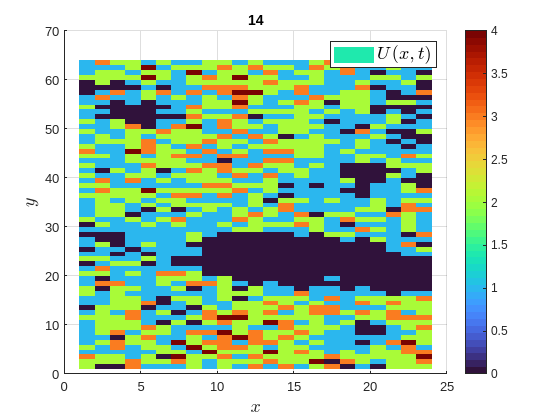

plotgap=10;
plot_distrib;

Choose model library

% local autonomous operators
max_dx = [0 2];
max_dt = 0;
polys = 0:3;
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {};%@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

% local non-autonomous operators
driftpolys=[]; drifttrigs=[];
diffpolys=[0]; difftrigs=[]; crossdrift=0;

% non-local operators
dx = mean(diff(xs_obs{1}));
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[0:1],'Sing',[0],'Exp',[1./(2*dx:2*dx:10*dx)],'Singeps',[0.01],'svdtol',[1e-4]}};
% convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[0:3],'Sing',[0],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.0251 


Set weak discretization

phi_class = {1,1};
sm_x = 4; % set ratio of query-point gap to test function radius in spatial dims
sm_t = 4; % set ratio of query-point gap to test function radius in time 

% manually set test function params
p_x = 3; mxs = floor(length(xs_obs{1})/3);
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 12;
tau_t = []; k_t = []; tauhat_t = [];

% set test function params using cornerpoint
% tauhat_x = 2; tau_x = 10^-8;
% p_x = []; mxs = 1;
% tauhat_t = 2; tau_t = 10^-8;
% p_t = []; mts = 1;

% rescale coordinates
scales = 2;

% use approx. variance for improved conditioning
covtol = 0;

% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-2;

set_discretization;

ET_setdisc = 0.2820 


View average FFT info

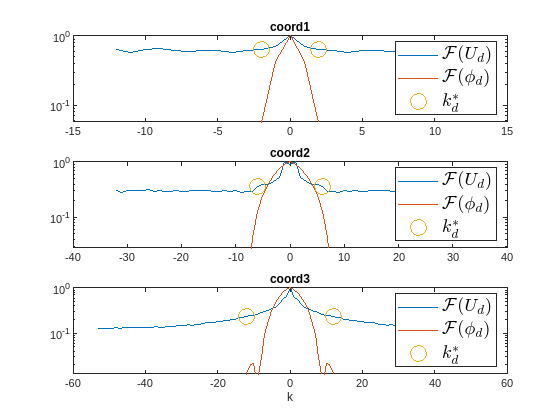

toggle_plot_fft = 1;
plot_Ufft;

Build linear systems

build_Gb;

ET_build_Gb = 0.4329 


MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 1/(0.01*size(G,2)+1);
maxits = Inf;
sparsity_scale = 0;
excl_tags= {'([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols = [0.1];
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 0.5230 


get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = 0.0208836u^{0}_{} + -0.383294u^{1}_{} + 0.528203u^{2}_{} + -0.125828u^{3}_{} + 0.100001([x.^0.*y.^0.*t.^0]u^1)_{lap} + 0.135015conve0.030201 + -1.4404conve0.015101 + 5.91967conve0.010067 + -9.63741conve0.0075503 + 5.35469conve0.0060403 + 0.00148074convmon0 + -0.000198529convsing0
Relative Res: ||b-G*W||_2/||b||_2 = 5.78e-01TP Score = NaN
      
polys = 0 1 2 3 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 8 12 
[s_x s_t] = 2 3 
[p_x p_t] = 3 3 
 scales = 2.55e+00 1.85e-02 1.85e-02 6.25e-01 
      
Total particles = 6250 
Size of dataset = 24 64 105 
Size G = 2507 13 
Cond G = 3.77e+10
[lambda_hat gamma] = 1.000e-04 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 1 
 
ET_load_data = 0.0874 
ET_build_lib = 0.0251 
ET_setdisc = 0.2820 
ET_build_Gb = 0.4329 
ET_solve_sparse_reg = 0.5230 
Elapsed time WSINDy = 1.3505 


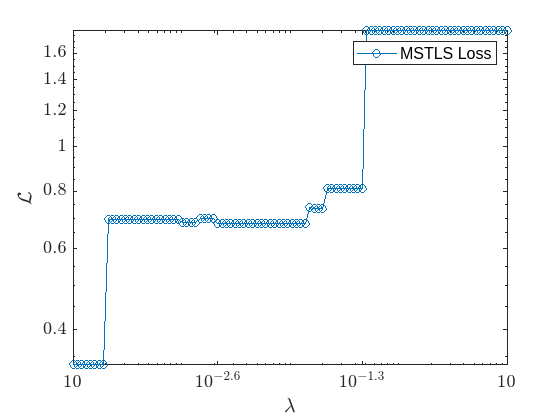

% Display loss
toggle_plot_loss = 1;
plot_loss;

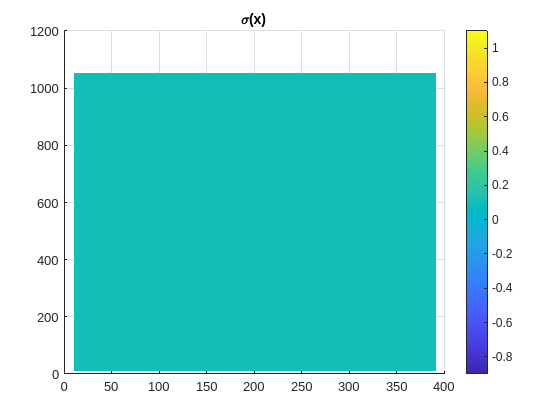

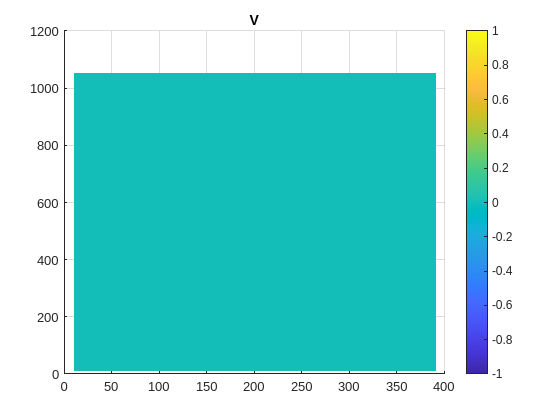

% Display drift/diffusion
toggle_plot_drift = 1;
plot_driftdiff;

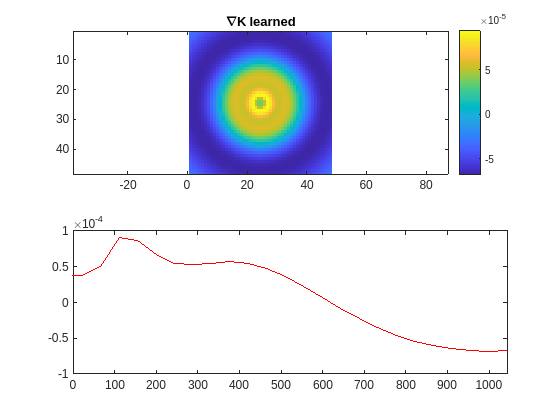


% Display interaction force
toggle_plot_IPforce = 1;
plot_K